clear all; close all;

## Load data

load("Observation_nb.mat");                                         % load data
X = y;                                          % 4-channel received signals 
fs = fs;                                          % sample rate (Hz)

## Plot waveform

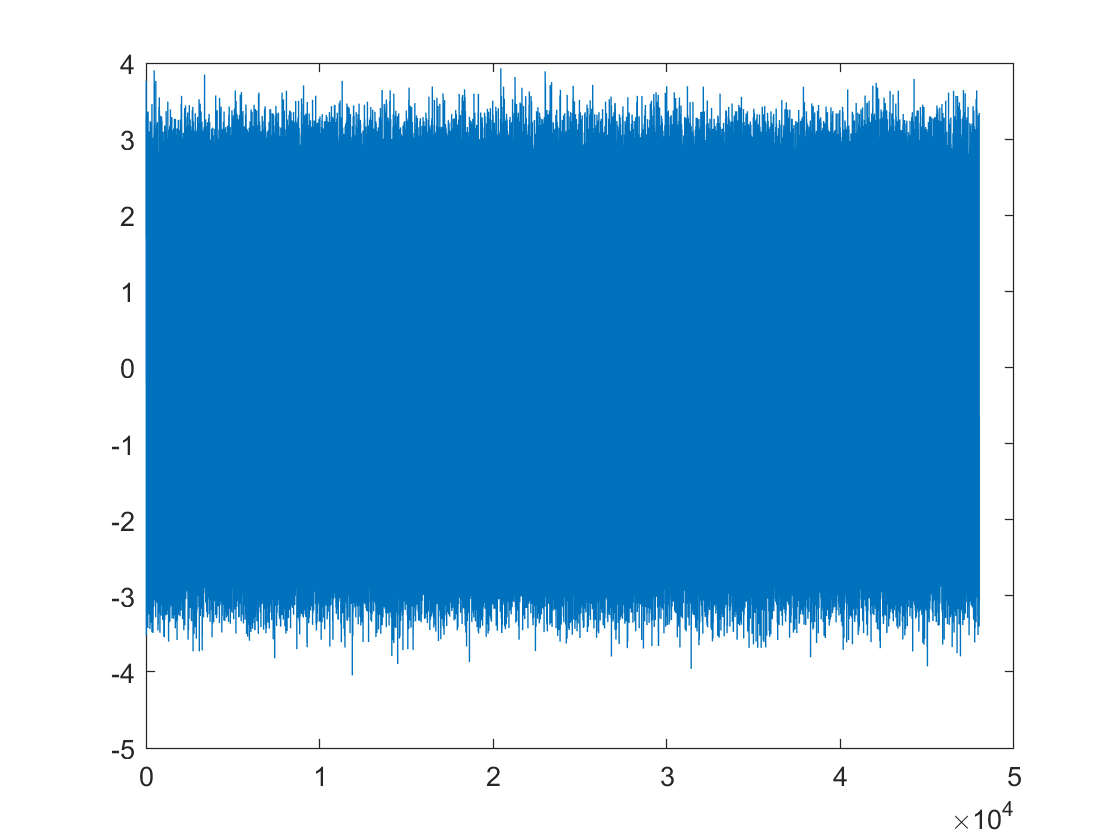

plot(real(y(:,1)));

## Array setup

[Frame,nSensors] = size(X);                            
J = nSensors;                                      % number of sensors
dx = 3.4e-2;                                            % inter-sensor distance in x direction (m)
dy = 0;                                             % sensor distance in y direction (m)
c = 340;                                           % sound velocity  (m)
n_source = 2;                                      % number of sources
Index = linspace(0,J-1,J);
p = (-(J-1)/2 + Index.') * [dx dy];                    % sensor position

## Plot sensor positions

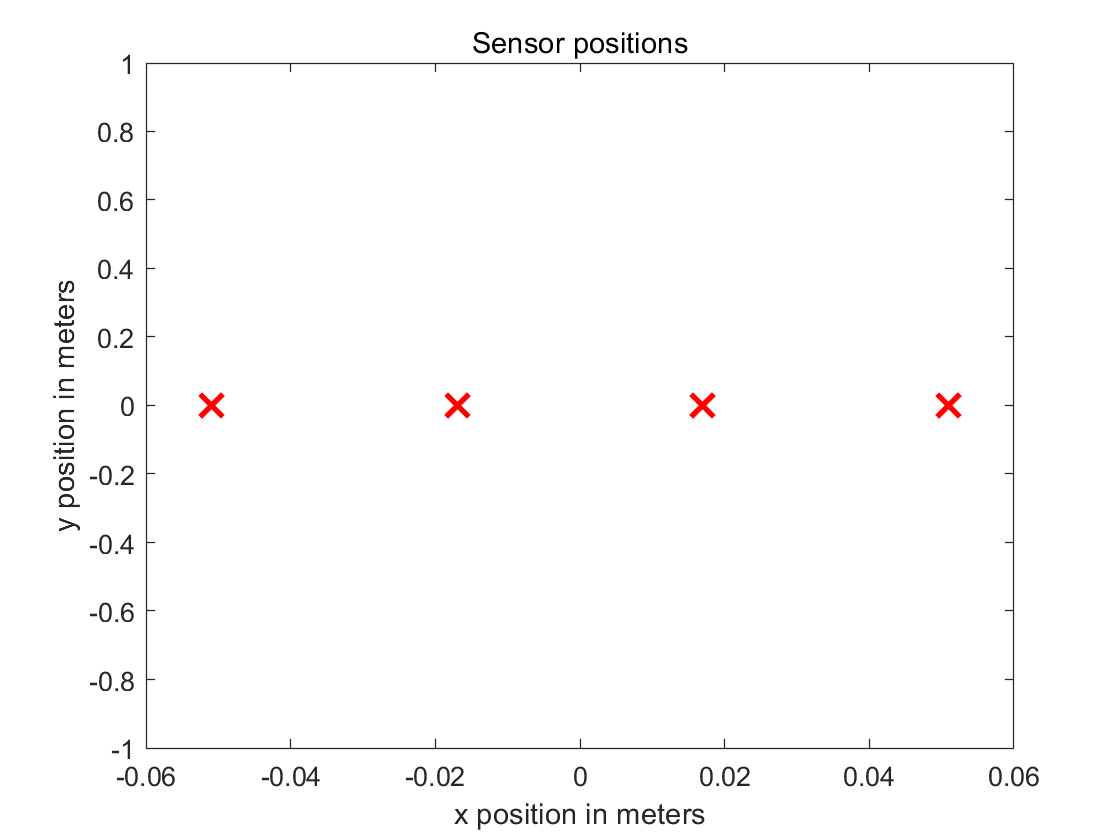

linspec = {'rx','MarkerSize',12,'LineWidth',2};
figure
plot(p(:,1),p(:,2),linspec{:});  
title('Sensor positions');
xlabel('x position in meters');
ylabel('y position in meters');

disp('The four microphones are ready !');

The four microphones are ready !


## DoA estimation (MUSIC)

stride = 0.1;                                             % determine the angular resolution(deg)
theta = -90:stride:90;                                 % grid
f_c = 0;                                               % center frequency  (Hz)
fb=0;
yy=fft(y,fs,1);
for kk=1:4
    for j=2:length(yy(:,kk))-1
        ans=yy(j-1,kk)+yy(j,kk)+yy(j+1,kk);
        if(ans>fb)
            fb=ans;
            f_c=j;
        end
    end
end
f_c=2300;
R_x =transpose(y)*y;                                            %  autocorrelation estimate
v =  [sin(theta*pi/180);-cos(theta*pi/180)];    
% direction vector  
cp0=complex(0,0);
szz=size(theta);
%a_theta=zeros([4 1801]);
kkk=[];
%{
for i=0:3
    aaaa=-2*pi*dx*sin(theta*pi/180)*fs/c*i;
    k=exp(complex(0,aaaa));
    kkk=[kkk k];
    size(a_theta(i+1,:))
    size(k)
    a_theta(i+1,:)=a_theta(i+1,:)+k;
end% steer vector
%}
tao=p*v/c;
a_theta=exp(complex(0,-2*pi*f_c*tao));
% implement eigen-decomposition and obtain the pseudo spectrum

% noise subspace (columns are eigenvectors), size: J*(J-n_source)
[xxx, yyy] = eig(R_x);
EVA=diag(yyy)';  
[EVA,I]=sort(EVA);
xxx=fliplr(xxx(:,I));   
U_n  = xxx(:, n_source+1: J);   
P_sm = 1./diag((a_theta')*(U_n*U_n')*a_theta)  ;      % pseudo music power

## Plot the MUSIC pseudo power spectrum

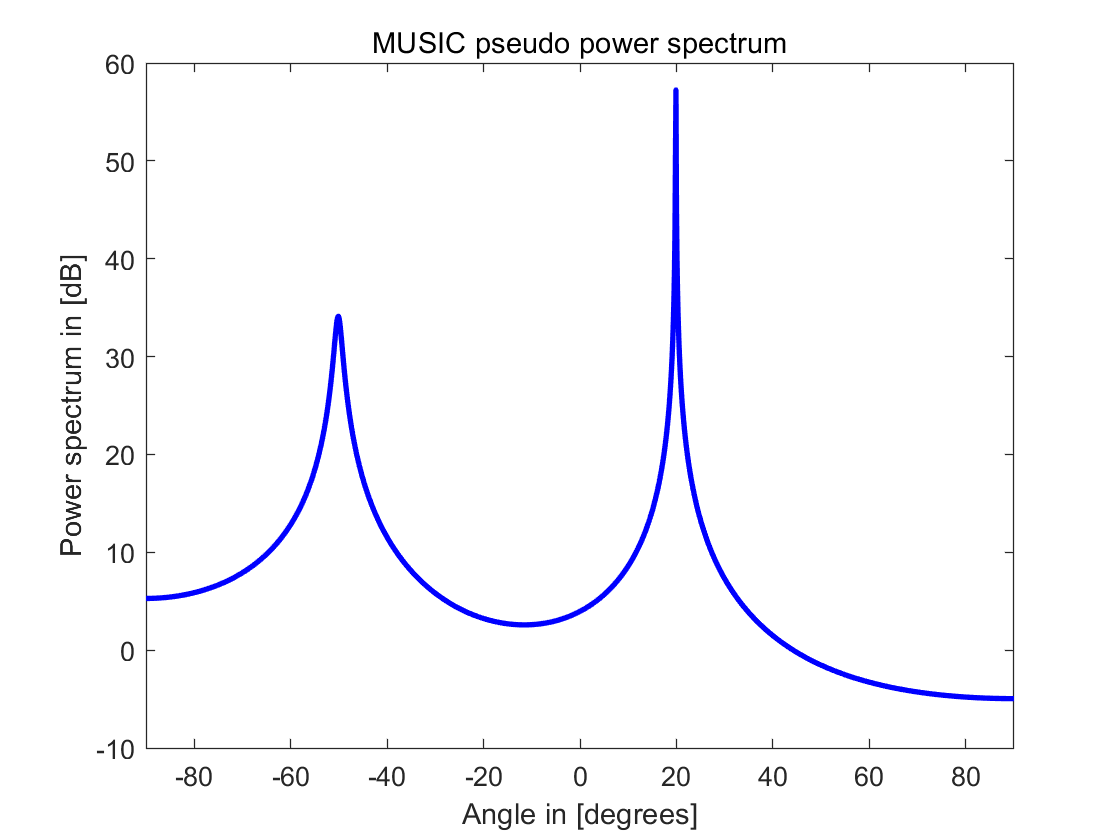

figure;
linspec = {'b-','LineWidth',2};
plot(theta, 10*log10(abs(P_sm)), linspec{:});
title('MUSIC pseudo power spectrum')
xlabel('Angle in [degrees]');
ylabel('Power spectrum in [dB]');
xlim([-90,90]);

## Find the local maximum and visualization

P_middle = abs(P_sm(2:end-1));
P_front = abs(P_sm(1:end-2));
P_back = abs(P_sm(3:end));
logic_front = (P_middle - P_front)>0;
logic_back = (P_middle - P_back)>0;
logic = logic_front & logic_back;
P_middle(~logic) = min(P_middle);
P_local = [abs(P_sm(1));P_middle;abs(P_sm(end))];
[~,doa_Idx] = maxk(P_local,n_source);
doa = theta(doa_Idx);
[~,minIdx] = min(abs(doa));
doa_source = doa(minIdx);
[~,maxIdx] = max(abs(doa));
interfer = doa(maxIdx);
disp(['The desired source DOA with MUSIC is: ',num2str(doa_source),' deg']);

The desired source DOA with MUSIC is: 19.9 deg


disp(['The interfering DOA with MUSIC is: ',num2str(interfer),' deg']);

The interfering DOA with MUSIC is: -50.1 deg
